Bogdan Vitoc

My fruit is the *yummy *eggplant!

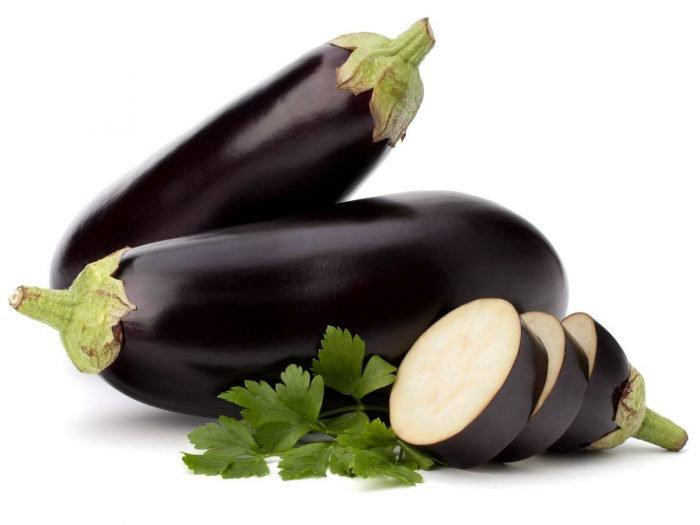

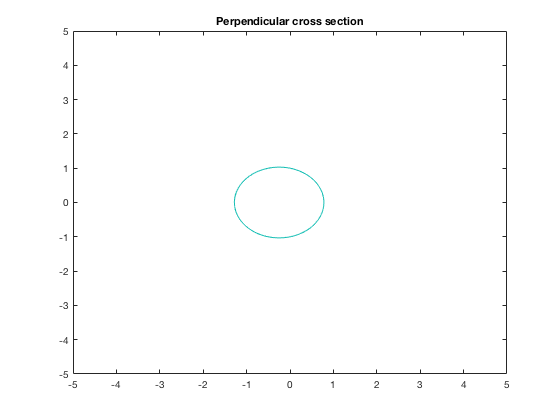

x = linspace(-5, 5, 500);
y = x;

[xgrid, ygrid] = meshgrid(x, y);

% Perpendicular cross section
a=2; b=0; c=2; d=1; e=0; f=-2;
contour(xgrid, ygrid, quadric(xgrid, ygrid, a, b, c, d, e, f), [0,0])
title('Perpendicular cross section')

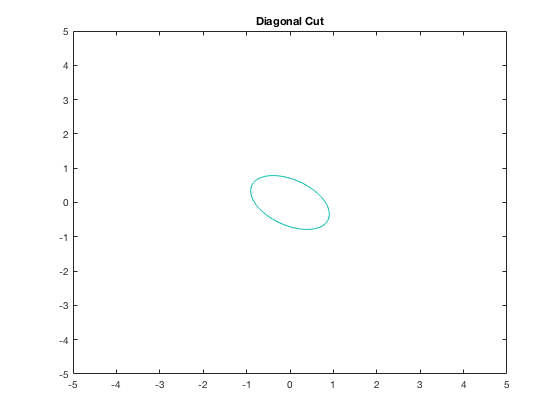


% Diagonal Cut
a=3; b=3; c=4; d=0; e=0; f=-2;
contour(xgrid, ygrid, quadric(xgrid, ygrid, a, b, c, d, e, f), [0,0])
title('Diagonal Cut')

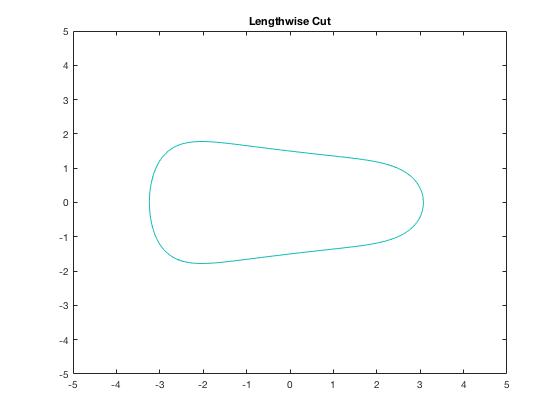


% Lengthwise Cut
a=6; b=20; c=2.3; d=0.05; e=2; f=1.5; g=2; h=0.2;
contour(xgrid, ygrid, eggplant(xgrid, ygrid, a, b, c, d, e, f, g, h), [0,0])
title('Lengthwise Cut')

function res = quadric(x,y,a,b,c,d,e,f)
    res = a.*x.^2 + b.*x.*y + c.*y.^2 + d.*x + e.*y + f;
end

function res = eggplant(x,y,a,b,c,d,e,f,g,h)
    res = abs(x.^a/b.^c).*(exp(d.*x)) + abs(y.^e/f.^g).*(exp(h.*x)) - 1;
end